clear all
d1=load("precipitation\PPT_zscore.mat");
d2=load("Soil moisture\SM_zscore.mat");
d3=load("L band VOD\VOD_zscore.mat");
d4=load("SIF data\SIF_zscore.mat");
d5=load("SPI weekly\SPI_1month_08_18.mat");
d6=load("VODCA VOD\VOD_X_zscore.mat");
d7=load("VODCA VOD\VOD_C_zscore.mat");


ppt=d1.Z(:,:,1:132);
sm=d2.Z(:,:,1:132);
vod=d3.Z(:,:,1:132);
sif=d4.Z(:,:,1:132);
spi=d5.SPI(:,:,1:132);
vod_x=d6.Z(:,:,1:132);
vod_c=d7.Z(:,:,1:132);

x1=80;
y1=59;
mon=[6 7 8 9 10 11 12];        %for a particular month
nmon=["june","july","august","september","october","november","december"];
year=(2010:2018)';

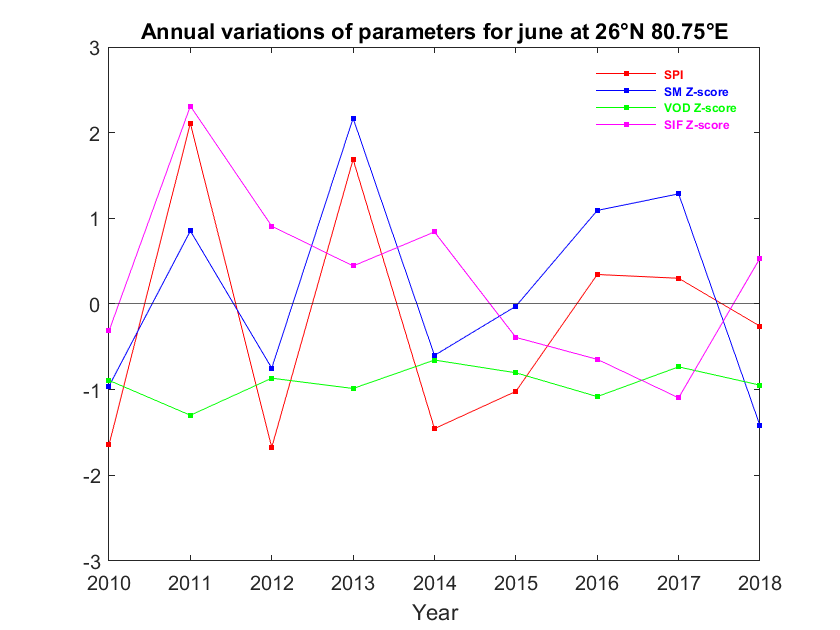

z=1;
for x=x1         %lat values 2:130
    for y=y1     %long values 2:136
        
        lat=spi(x,1,1);
        long=spi(1,y,1);
        spival=zeros(9,1);
        smval=zeros(9,1);
        vodval=zeros(9,1);
        sifval=zeros(9,1);
        p=1;
        
        for i=25:132                 %getting values for that month in each year
            
            month=rem(spi(1,1,i),100);
            
            if month==mon(z)
                spival(p)=spi(x,y,i);
                smval(p)=sm(x,y,i);
                vodval(p)=vod_x(x,y,i);
                sifval(p)=sif(x,y,i);
                p=p+1;
            end
            
        end
        
        %%plotting the grap
        
        if length(spival(isnan(spival)))/length(spival)==1 || length(smval(isnan(smval)))/length(smval)==1 || length(vodval(isnan(vodval)))/length(vodval)==1 || length(sifval(isnan(sifval)))/length(sifval)==1
            continue;
        else
            f1=figure(1);
            plot(year,spival,"-s",'MarkerSize',3,'MarkerEdgeColor','red','MarkerFaceColor',"red","Color","red")
            ylim([-3 3])
            hold on
            plot(year,smval,"-s",'MarkerSize',3,'MarkerEdgeColor','b','MarkerFaceColor',"b","Color","b")
            ylim([-3 3])
            hold on
            plot(year,vodval,"-s",'MarkerSize',3,'MarkerEdgeColor','g','MarkerFaceColor',"g","Color","g")
            ylim([-3 3])
            hold on
            plot(year,sifval,"-s",'MarkerSize',3,'MarkerEdgeColor','m','MarkerFaceColor',"m","Color","m")
            ylim([-3 3])
            j=yline(0);
            j.Annotation.LegendInformation.IconDisplayStyle = 'off';
            lgd=legend("\color{red}\bf SPI","\color{blue}\bf SM Z-score","\color{green}\bf VOD Z-score","\color{magenta}\bf SIF Z-score");
            lgd.FontSize=6;
            legend boxoff;
            xlabel("Year");
            title("Annual variations of parameters for "+nmon(z)+" at "+num2str(lat)+"°N "+num2str(long)+"°E");
            nam=num2str(lat)+"N_"+num2str(long)+"E";
%             saveas(f,"E:\MTP2\time series\annual variaton\4 north east india\11\"+nam+".png");
%             clear figure(1);
%             clear f;
%             close;
            hold off;
        end
    end
end

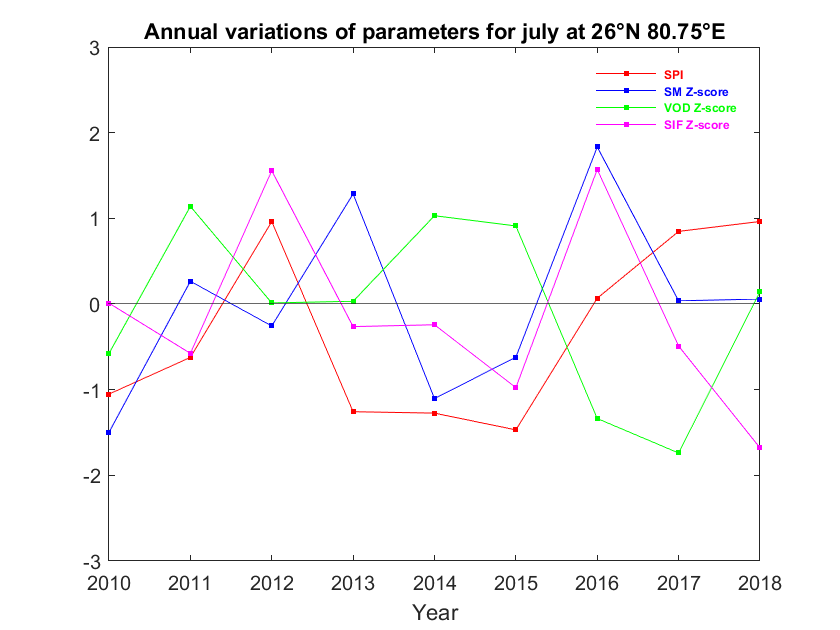

z=2;
for x=x1         %lat values 2:130
    for y=y1     %long values 2:136
        
        lat=spi(x,1,1);
        long=spi(1,y,1);
        spival=zeros(9,1);
        smval=zeros(9,1);
        vodval=zeros(9,1);
        sifval=zeros(9,1);
        p=1;
        
        for i=25:132                 %getting values for that month in each year
            
            month=rem(spi(1,1,i),100);
            
            if month==mon(z)
                spival(p)=spi(x,y,i);
                smval(p)=sm(x,y,i);
                vodval(p)=vod_x(x,y,i);
                sifval(p)=sif(x,y,i);
                p=p+1;
            end
            
        end
        
        %%plotting the grap
        
        if length(spival(isnan(spival)))/length(spival)==1 || length(smval(isnan(smval)))/length(smval)==1 || length(vodval(isnan(vodval)))/length(vodval)==1 || length(sifval(isnan(sifval)))/length(sifval)==1
            continue;
        else
            f2=figure(2);
            plot(year,spival,"-s",'MarkerSize',3,'MarkerEdgeColor','red','MarkerFaceColor',"red","Color","red")
            ylim([-3 3])
            hold on
            plot(year,smval,"-s",'MarkerSize',3,'MarkerEdgeColor','b','MarkerFaceColor',"b","Color","b")
            ylim([-3 3])
            hold on
            plot(year,vodval,"-s",'MarkerSize',3,'MarkerEdgeColor','g','MarkerFaceColor',"g","Color","g")
            ylim([-3 3])
            hold on
            plot(year,sifval,"-s",'MarkerSize',3,'MarkerEdgeColor','m','MarkerFaceColor',"m","Color","m")
            ylim([-3 3])
            j=yline(0);
            j.Annotation.LegendInformation.IconDisplayStyle = 'off';
            lgd=legend("\color{red}\bf SPI","\color{blue}\bf SM Z-score","\color{green}\bf VOD Z-score","\color{magenta}\bf SIF Z-score");
            lgd.FontSize=6;
            legend boxoff;
            xlabel("Year");
            title("Annual variations of parameters for "+nmon(z)+" at "+num2str(lat)+"°N "+num2str(long)+"°E");
            nam=num2str(lat)+"N_"+num2str(long)+"E";
%             saveas(f,"E:\MTP2\time series\annual variaton\4 north east india\11\"+nam+".png");
%             clear figure(1);
%             clear f;
%             close;
               hold off;
        end
    end
end

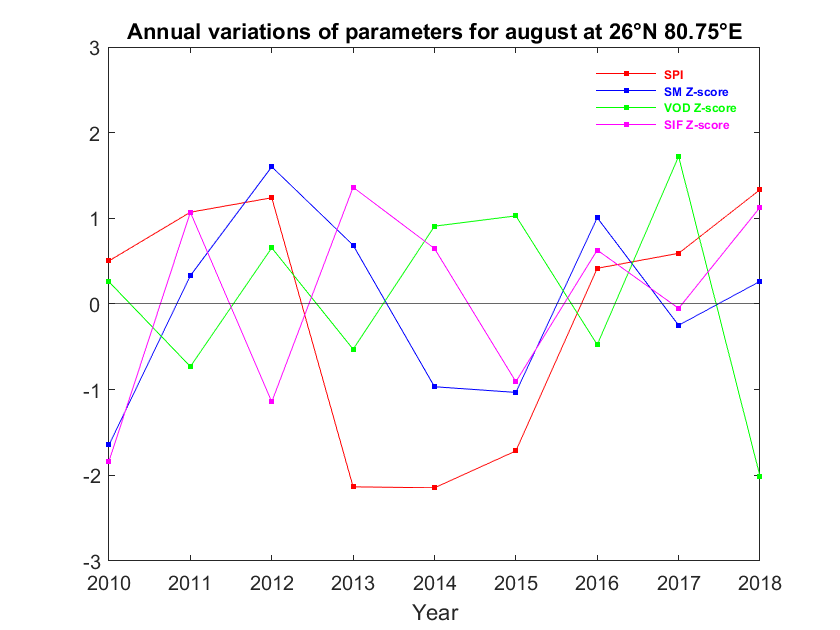

z=3;
for x=x1         %lat values 2:130
    for y=y1     %long values 2:136
        
        lat=spi(x,1,1);
        long=spi(1,y,1);
        spival=zeros(9,1);
        smval=zeros(9,1);
        vodval=zeros(9,1);
        sifval=zeros(9,1);
        p=1;
        
        for i=25:132                 %getting values for that month in each year
            
            month=rem(spi(1,1,i),100);
            
            if month==mon(z)
                spival(p)=spi(x,y,i);
                smval(p)=sm(x,y,i);
                vodval(p)=vod_x(x,y,i);
                sifval(p)=sif(x,y,i);
                p=p+1;
            end
            
        end
        
        %%plotting the grap
        
        if length(spival(isnan(spival)))/length(spival)==1 || length(smval(isnan(smval)))/length(smval)==1 || length(vodval(isnan(vodval)))/length(vodval)==1 || length(sifval(isnan(sifval)))/length(sifval)==1
            continue;
        else
            f3=figure(3);
            plot(year,spival,"-s",'MarkerSize',3,'MarkerEdgeColor','red','MarkerFaceColor',"red","Color","red")
            ylim([-3 3])
            hold on
            plot(year,smval,"-s",'MarkerSize',3,'MarkerEdgeColor','b','MarkerFaceColor',"b","Color","b")
            ylim([-3 3])
            hold on
            plot(year,vodval,"-s",'MarkerSize',3,'MarkerEdgeColor','g','MarkerFaceColor',"g","Color","g")
            ylim([-3 3])
            hold on
            plot(year,sifval,"-s",'MarkerSize',3,'MarkerEdgeColor','m','MarkerFaceColor',"m","Color","m")
            ylim([-3 3])
            j=yline(0);
            j.Annotation.LegendInformation.IconDisplayStyle = 'off';
            lgd=legend("\color{red}\bf SPI","\color{blue}\bf SM Z-score","\color{green}\bf VOD Z-score","\color{magenta}\bf SIF Z-score");
            lgd.FontSize=6;
            legend boxoff;
            xlabel("Year");
            title("Annual variations of parameters for "+nmon(z)+" at "+num2str(lat)+"°N "+num2str(long)+"°E");
            nam=num2str(lat)+"N_"+num2str(long)+"E";
%             saveas(f,"E:\MTP2\time series\annual variaton\4 north east india\11\"+nam+".png");
%             clear figure(1);
%             clear f;
%             close;
            hold off;
        end
    end
end

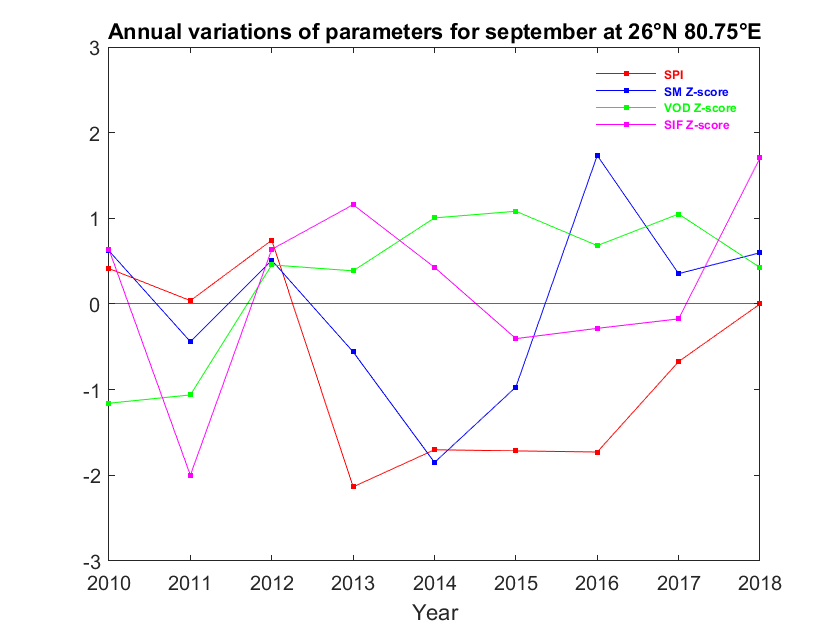

z=4;
for x=x1         %lat values 2:130
    for y=y1     %long values 2:136
        
        lat=spi(x,1,1);
        long=spi(1,y,1);
        spival=zeros(9,1);
        smval=zeros(9,1);
        vodval=zeros(9,1);
        sifval=zeros(9,1);
        p=1;
        
        for i=25:132                 %getting values for that month in each year
            
            month=rem(spi(1,1,i),100);
            
            if month==mon(z)
                spival(p)=spi(x,y,i);
                smval(p)=sm(x,y,i);
                vodval(p)=vod_x(x,y,i);
                sifval(p)=sif(x,y,i);
                p=p+1;
            end
            
        end
        
        %%plotting the grap
        
        if length(spival(isnan(spival)))/length(spival)==1 || length(smval(isnan(smval)))/length(smval)==1 || length(vodval(isnan(vodval)))/length(vodval)==1 || length(sifval(isnan(sifval)))/length(sifval)==1
            continue;
        else
            f4=figure(4);
            plot(year,spival,"-s",'MarkerSize',3,'MarkerEdgeColor','red','MarkerFaceColor',"red","Color","red")
            ylim([-3 3])
            hold on
            plot(year,smval,"-s",'MarkerSize',3,'MarkerEdgeColor','b','MarkerFaceColor',"b","Color","b")
            ylim([-3 3])
            hold on
            plot(year,vodval,"-s",'MarkerSize',3,'MarkerEdgeColor','g','MarkerFaceColor',"g","Color","g")
            ylim([-3 3])
            hold on
            plot(year,sifval,"-s",'MarkerSize',3,'MarkerEdgeColor','m','MarkerFaceColor',"m","Color","m")
            ylim([-3 3])
            j=yline(0);
            j.Annotation.LegendInformation.IconDisplayStyle = 'off';
            lgd=legend("\color{red}\bf SPI","\color{blue}\bf SM Z-score","\color{green}\bf VOD Z-score","\color{magenta}\bf SIF Z-score");
            lgd.FontSize=6;
            legend boxoff;
            xlabel("Year");
            title("Annual variations of parameters for "+nmon(z)+" at "+num2str(lat)+"°N "+num2str(long)+"°E");
            nam=num2str(lat)+"N_"+num2str(long)+"E";
%             saveas(f,"E:\MTP2\time series\annual variaton\4 north east india\11\"+nam+".png");
%             clear figure(1);
%             clear f;
%             close;
            hold off;
        end
    end
end